Tuning del controllore


$$P(s)=\frac{1}{Js}$$
    


$$C(s)=K_p+K_i/s=\frac{K_p s +K_i}{s}$$



$$L(s)=\frac{K_p s + K_i}{Js^2}$$



$$F=\frac{L}{1+L}=\frac{K_p s+ K_i}{J s^2+ K_p s + K_i}=\frac{K_p/J s +K_i/J}{s^2+K_p/J s+ K_i/J}$$


impongo i poli del denominatore, ad esempio perchè sia uguali e coincidenti e pari a $\omega_F$


$$F=\frac{num(s)}{s^2+2\omega_f s +\omega_f^2}$$



$$K_i/J=\omega_F \rightarrow K_i=\omega_F^2J$$



$$K_p/J=2\omega_F \rightarrow K_p=2\omega_FJ$$


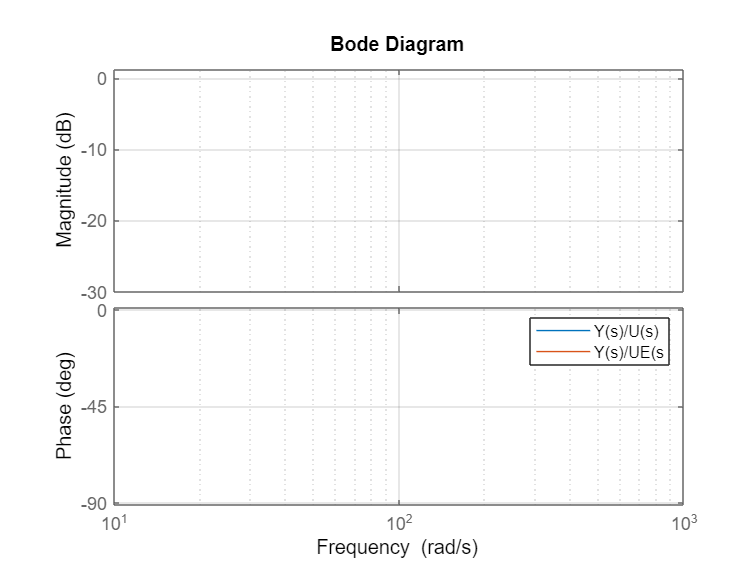

J=0.2;
omegaF=50;
Kp=2*omegaF*J;
Ki=omegaF^2*J;
C=Kp+Ki/s;

P=1/(J*s);
dt=1e-3;

L=P*C;
F=L/(1+L);
F_y_uE=P/(1+L);
F_uC_uE=-L/(1+L);
F_u_uE=1/(1+L);

bode(P,L,F)
grid on
legend('Y(s)/U(s)','Y(s)/E(s)','Y(s)/UE(s')